# TP4 - Détection de contours et recherche des maxima locaux

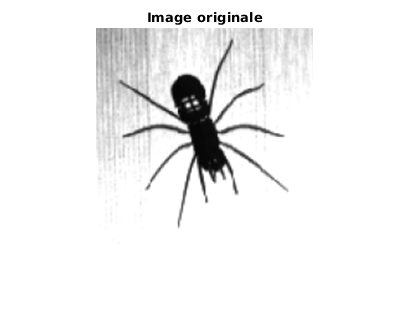

figure;
bruiter = false;
variance = 0.005;
path = "../../resource/NG/araignee.png";
I = imread(path);
if bruiter
   I = imnoise(I,'gaussian',0,variance);
end
[W,H] = size(I);
imshow(I);
title("Image originale")

## Partie 1 - Détection de contours

### Gradient simple

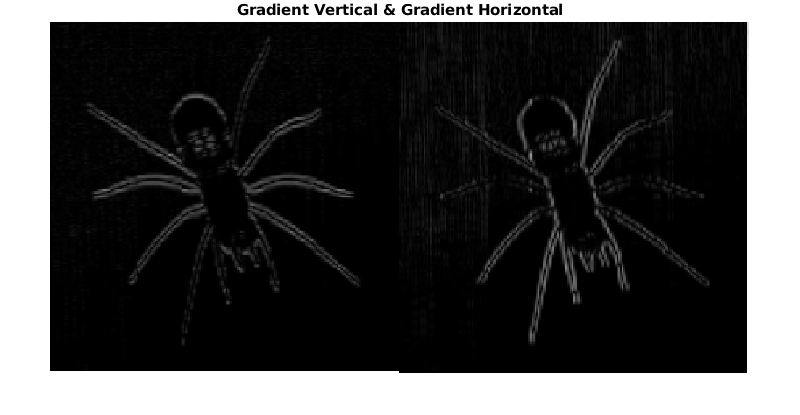

gradient_H = [-1 1];
gradient_V = [-1;1];

I_gradient_H = uint8(abs(filter2(gradient_H,I)));
I_gradient_V = uint8(abs(filter2(gradient_V,I)));
I_gradient_HV = abs(I_gradient_V+I_gradient_H);

figure;
montage([I_gradient_V I_gradient_H])
title("Gradient Vertical & Gradient Horizontal")

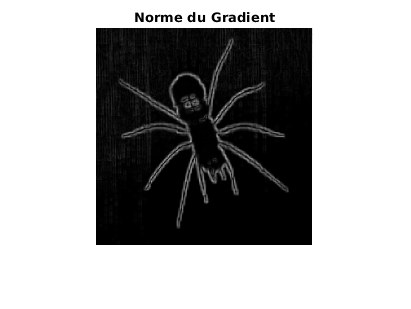

figure;

imshow(I_gradient_HV)
title("Norme du Gradient")

### Gradients de Roberts, Sobel, Prewitt et filtre de Canny (NG)

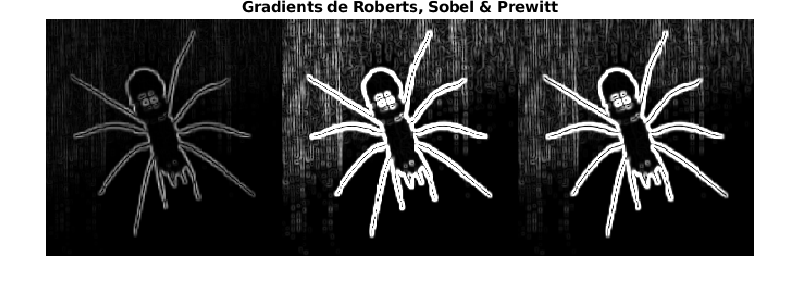

I_gradient_roberts = uint8(imgradient(I,"roberts"));
I_gradient_sobel = uint8(imgradient(I,"sobel"));
I_gradient_prewitt = uint8(imgradient(I,"prewitt"));

montage([I_gradient_roberts I_gradient_sobel I_gradient_prewitt])
title("Gradients de Roberts, Sobel & Prewitt");

#### Seuilage :

methode = "roberts";
seuil = 24;
seuil = seuil/255

seuil = 0.0941

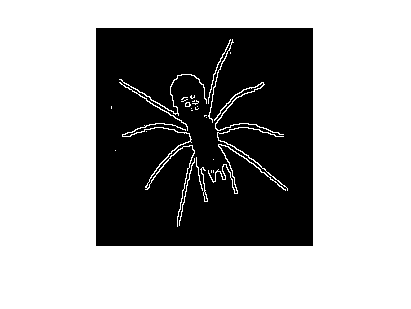

I_seuillee = edge(I,methode,seuil);
figure;
imshow(I_seuillee);

### Laplacien 4-connexe et 8-connexe

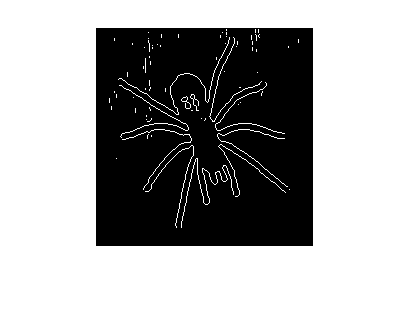

seuil = 0.0088;
laplacien4 = [ 0 1 0 ; 1 -4 1 ; 0 1 0];
laplacien8 = [ 1 1 1 ; 1 -8 1 ; 1 1 1];
figure;
I_laplacien = edge(I,'zerocross',seuil);
imshow(I_laplacien);

## Recherche des maxima locaux pour la norme du gradient


gradient_H = [-1 1];
gradient_V = [-1;1];
I2 = [2 0 0 ; 2 12 60 ; 2 1 0 ; 2 51 50];
Gx = filter2(gradient_H,I2);
Gy = filter2(gradient_V,I2);
G = abs(Gx)+abs(Gy);
angleTan = atan(Gy./Gx)

angleTan =          0    1.5708    1.5708
         0   -0.2253    0.7854
         0   -1.5508    1.5708
   -0.0408    1.5512    0.7854


[H,V] = size(I2);
I2=G;
I2c = conv2(I2,[0 0 0 ; 0 1 0 ; 0 0 0])

I2c =      0     0     0     0     0
     0     2    12    60     0
     0    10    59   120     0
     0     1    51    50     0
     0    51    52   100     0
     0     0     0     0     0


MLoco = zeros(H,V)

MLoco =      0     0     0
     0     0     0
     0     0     0
     0     0     0



for y = 1:V
    for x = 1:H
          if angleTan(x,y)>=-pi/8 && angleTan(x,y)<=pi/8
                if I2c(x+2,y+1)<I2c(x+1,y+1) && I2c(x,y+1)<I2c(x+1,y+1)
                    MLoco(x,y) = I2c(x+1,y+1);
                else
                    MLoco(x,y) = 1;
                end
          end
          if angleTan(x,y)>=pi/8 && angleTan(x,y)<=3*pi/8
                if I2c(x+2,y)<I2c(x+1,y+1) && I2c(x,y+2)<I2c(x+1,y+1)
                    MLoco(x,y) = I2c(x+1,y+1);
                else
                    MLoco(x,y) = 1;
                end
          end
          if angleTan(x,y)>=-3*pi/8 && angleTan(x,y)<=-pi/8
                if I2c(x,y)<I2c(x+1,y+1) && I2c(x+2,y+2)<I2c(x+1,y+1)
                    MLoco(x,y) = I2c(x+1,y+1);
                else
                    MLoco(x,y) = 1;
                end
          end
          if angleTan(x,y)>=3*pi/8 && angleTan(x,y)<=pi/2 || angleTan(x,y)>=-pi/2 && angleTan(x,y)<=-3*pi/8
                if I2c(x+1,y)<I2c(x+1,y+1) && I2c(x+1,y+2)<I2c(x+1,y+1)
                    MLoco(x,y) = I2c(x+1,y+1);
                else
                    MLoco(x,y) = 1;
                end
          end 
    end
end
MLoco

MLoco =      1     1    60
    10    59   120
     1    51     1
    51     1   100
